clc; clear; close all;


## Key

d=15e-3; % m
r=d/2; % m
T=43; % Nm
F=T/r % N

F = 5.7333e+03

keyWidth=5; % mm
keyLength=23-5; % mm
A_shear=keyLength*keyWidth; % mm2
tau_xy=F/A_shear % MPa

tau_xy = 63.7037

A_bearing=keyWidth/2*keyLength; % mm2
sigma_x=F/A_bearing % MPa 

sigma_x = 127.4074

## Spline

N=36;
d=3/4;
pd=N/d

pd = 48

a=(1/2)/pd;
b=(1.25/2)/pd;
inTmm=25.4;

dr=(d-2*b)*inTmm*10^-3

dr = 0.0184

do=(d+2*a)*inTmm*10^-3

do = 0.0196

d=d*inTmm*10^-3

d = 0.0190

di=17*10^-3

di = 0.0170


l=(dr^3*(1-(di^4/dr^4)))/d^2

l = 0.0046

tau=((16*T)/(pi*d^2*l))*10^-6

tau = 130.6775

## SN diagram

d=15e-3

d = 0.0150

Sy=235

Sy = 235

Sut=360

Sut = 360



Cload=1

Cload = 1

Csize=1.189*(sqrt((0.0766*d^2)/0.0766))^(-0.097*d^2)

Csize = 1.1891

Csurf=4.51*Sut^-0.256

Csurf = 0.9995

Ctemp=1

Ctemp = 1

Creliab=0.702

Creliab = 0.7020


Se=0.5*Sut

Se = 180

Se=Se*Creliab*Ctemp*Csurf*Csize*Cload

Se = 150.1739

Sm=0.9*Sut*0.8

Sm = 259.2000

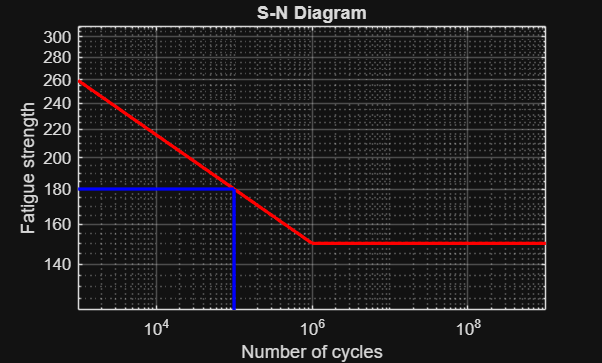



% Known fatigue points
N1 = 1e3;
S1 = Sm;

N2 = 1e6;
S2 = Se;

% Basquin constants
b = (log10(S2) - log10(S1)) / (log10(N2) - log10(N1));
a = S1 / (N1^b);

% Cycle ranges
N_low = logspace(3,6,200);
S_low = a*N_low.^b;

N_high = logspace(6,9,200);
S_high = Se*ones(size(N_high));

% Stress at 10^5 cycles
N_test = 1e5;
S_test = a*N_test^b;

% Plot S-N diagram
figure
loglog(N_low,S_low,'r','LineWidth',2)
hold on
loglog(N_high,S_high,'r','LineWidth',2)

% Pink guide lines
loglog([N_test N_test],[1 S_test],'b','LineWidth',2)
loglog([1e3 N_test],[S_test S_test],'b','LineWidth',2)

grid on
xlabel('Number of cycles')
ylabel('Fatigue strength')
title('S-N Diagram')

xlim([1e3 1e9])
ylim([Se*0.8 Sm*1.2])

## Goodman diagram